# Model Comparison of Cone vs Combined vs Rod circuit

This script is based on the PAL_PFLR_Demo.m script from the Palamedes toolbox. That script has a ton of text at the top describing the routine. Basically, it uses the PAL_PFML_FitMultiple function to compare a full model (2 PF, i.e. independent curves) to a restricted model (1 PF, i.e. one curve for both conditions) via a Likelihood Ratio Test. 

The [Psychometrics textbook](https://www.sciencedirect.com/book/monograph/9780124071568/psychophysics#table-of-contents) and the [Palamedes website](https://www.palamedestoolbox.org/index.html) contain additional information. 

## Data and options

Loading data and setting parameters and options. 

%% 1. Load and Format Your Data
load('motionResults.mat'); % Contains allPulseDelay, probTMeansL, probTMeansR, params

% Setup Independent Variable (X-axis) in ms
xAxis = allPulseDelay .* 1000; 
NumConditions = 3; % Condition 1: Cone, Condition 2: Comb, Condition 3: Rod

% Format inputs as [NumConditions x NumStimLevels] matrices
StimLevels = repmat(xAxis, NumConditions, 1);

SuccessesCone = sum([probTMeansL.cone; probTMeansR.cone], 1);
SuccessesComb = sum([probTMeansL.comb; probTMeansR.comb], 1);
SuccessesRod = sum([probTMeansL.rod; probTMeansR.rod], 1);
NumPos = [SuccessesCone; SuccessesComb; SuccessesRod]; 

N_trials_per_delay = 2 * (params.repeats - params.sizeTrain);
OutOfNum = N_trials_per_delay .* ones(size(NumPos));

% Use the Weibull function as selected in defaultStatsPlots.m
PF = @PAL_Weibull; 

% Options for the Nelder-Mead optimization search
options = PAL_minimize('options');
% % % may need more options from PAL_PFLR_Demo.m % % %
% options.TolFun = 1e-12;     %Increase desired precision on LL
% options.TolX = 1e-12;       %Increase desired precision on parameters
% options.MaxFunEvals = 5000; %Allow more function evals
% options.MaxIter = 5000;     %Allow more iterations
% options.Display = 'off';    %suppress fminsearch messages
lapseLimits = [0 0.2];        %Range on lapse rates. Will go ignored here
%                             %if lapse rate is not a free parameter
maxTries = 4;               %Try each fit at most four times        
rangeTries = [2 1.9 0 0.1];   %Range of random jitter to apply to initial 
                            %parameter values on retries of failed fits.

The fit is pretty sensitive to the initial guesses. These values seemed to work well. I guess I can also set these initial guesses separately for the two conditions. The fit also did not do well when I specified lapseLimits (although I think I was way off with that range).

%Guesses for free parameters, fixed values for fixed parameters
paramsInit = [15, 1, 0.5, 0.01];    %or e.g.: [0 1 .5 0; 0 1 .5 0];

## Fit the '1 PF' model

The restricted model, a.k.a. the lesser model or the 1 PF model because it is the model for which we do only one fit to capture all conditions. That means that both conditions will share a common threshold, slope, and lapse rate for the psychometric curve. 

%% 3. Fit the Restricted Model (Constrained Equal)
% We force both conditions to share a single common threshold and slope.

[paramsL, LLRestr] = PAL_PFML_FitMultiple(...
    StimLevels, NumPos, OutOfNum, paramsInit, PF, ...
    'thresholds', 'constrained','slopes', 'constrained', ...
    'guessrates','fixed','lapserates','constrained',...
    'lapseLimits',lapseLimits, 'searchOptions', options);

% In 'equal' mode, Palamedes outputs the same shared parameters for both rows
sharedThreshold = paramsL(1,1);
sharedSlope = paramsL(1,2);
sharedLapseRate = paramsL(1,4);

[fprintf('--- Restricted Model Fit (Equal Curves) ---\n'), fprintf('Shared Threshold: %6.2f ms, Shared Slope: %6.2f, Shared LapseRate: %6.2f\n', sharedThreshold, sharedSlope, sharedLapseRate), fprintf('Total Log-Likelihood: %6.2f\n\n', LLRestr)];

--- Restricted Model Fit (Equal Curves) ---
Shared Threshold:  15.62 ms, Shared Slope:   1.27, Shared LapseRate:   0.01
Total Log-Likelihood: -75810.73



## Fit the '2 PF' model

The unconstrained model, a.k.a. the fuller model or the 2 PF model because 2 curves are fit (1 for each condition separately). That means each condition will have its own threshold, slope, and lapse rate for the psychometric curve. 

%% 2. Fit the Full Model (Unconstrained)
[paramsF, LLFull] = PAL_PFML_FitMultiple(...
    StimLevels, NumPos, OutOfNum, paramsL, PF, ...
    'thresholds', 'unconstrained', 'slopes', 'unconstrained', ...
    'guessrates','fixed','lapserates','unconstrained',...
    'lapseLimits',lapseLimits, 'searchOptions', options);

% Extract independent thresholds and slopes
thresholdsFull = paramsF(:,1);
slopesFull = paramsF(:,2);
lapseRatesFull = paramsF(:,4);

[fprintf('--- Full Model Fit (Separate Curves) ---\n'),fprintf('Cone -> Threshold: %6.2f ms, Slope: %6.2f, LapseRate: %6.2f\n', thresholdsFull(1), slopesFull(1), lapseRatesFull(1)),fprintf('Comb -> Threshold: %6.2f ms, Slope: %6.2f, LapseRate: %6.2f\n', thresholdsFull(2), slopesFull(2), lapseRatesFull(2)),fprintf('Rod -> Threshold: %6.2f ms, Slope: %6.2f, LapseRate: %6.2f\n', thresholdsFull(3), slopesFull(3), lapseRatesFull(3)),fprintf('Total Log-Likelihood: %6.2f\n\n', LLFull)];

--- Full Model Fit (Separate Curves) ---
Cone -> Threshold:  13.28 ms, Slope:   1.34, LapseRate:   0.01
Comb -> Threshold:  16.13 ms, Slope:   1.24, LapseRate:   0.00
Rod -> Threshold:  17.85 ms, Slope:   1.28, LapseRate:   0.02
Total Log-Likelihood: -75081.63



## Plot of data with model fits

Plotting the '2 PF' model with the actual data overlaid. The fit is pretty good, but it doesn't quite capture the curve down of the Cone condition. 

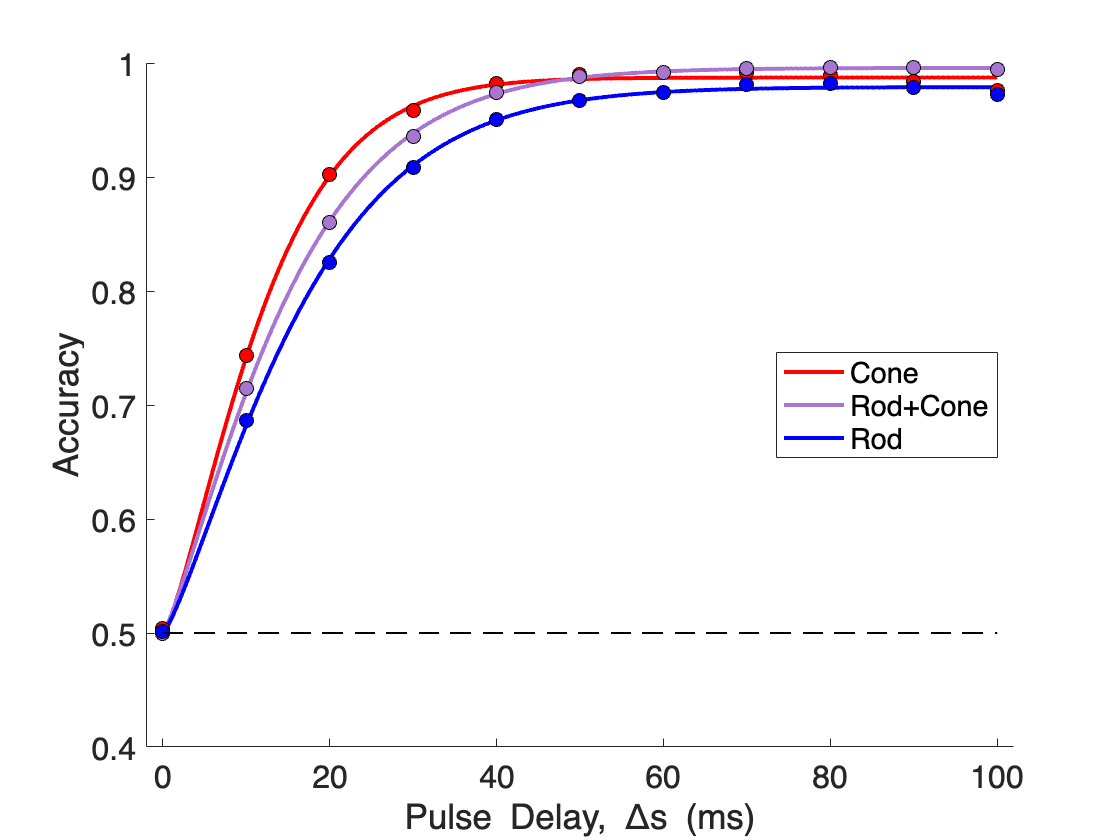

%plot fitted functions
figure; hold on
purpleColor = [0.66, 0.46, 0.82];

% condition the true data
ProportionCorrectObserved = NumPos ./ OutOfNum; 
StimLevelsFineGrain = [min(min(StimLevels)):(max(max(StimLevels) - ... 
    min(min(StimLevels))))./1000:max(max(StimLevels))];

% plot curve fits for full model
ProportionCorrectModel_Cone = PF(paramsF(1,:),StimLevelsFineGrain);
plot(StimLevelsFineGrain,ProportionCorrectModel_Cone,'-','linewidth',2,...
    'color','r');
ProportionCorrectModel_Comb = PF(paramsF(2,:),StimLevelsFineGrain);
plot(StimLevelsFineGrain,ProportionCorrectModel_Comb,'-','linewidth',2,...
    'color',purpleColor);
ProportionCorrectModel_Rod = PF(paramsF(3,:),StimLevelsFineGrain);
plot(StimLevelsFineGrain,ProportionCorrectModel_Rod,'-','linewidth',2,...
    'color','b');

% plot true data on top
plot(StimLevels(1,:),ProportionCorrectObserved(1,:),'ko','markersize',...
    7,'markerfacecolor','r');
plot(StimLevels(2,:),ProportionCorrectObserved(2,:),'ko','markersize',...
    7,'markerfacecolor',purpleColor);
plot(StimLevels(3,:),ProportionCorrectObserved(3,:),'ko','markersize',...
    7,'markerfacecolor','b');

% Plot Chance Line
plot([0 max(xAxis)], [0.5 0.5], 'k--', 'LineWidth', 1);

legend('Cone','Rod+Cone','Rod','Location','East')
xlabel('Pulse Delay, \Deltas (ms)');
ylabel('Accuracy'); %'Proportion Correct'
set(gca,'FontSize',16)
xlim([xAxis(1)-2, xAxis(end)+2])

## Model fit parameters

Compute standard errors of the fit parameters. This Bootstrap test uses the parameters from the 2 PF model. 

From Section 9.2.1 of the Psychophysics textbook: "For our current purposes we may loosely think of a standard error as the expected difference between the true parameter value and our estimate, based on the results of our experiment." 

% Parametric Bootstrap (1) or Non-Parametric Bootstrap (2)
ParOrNonPar = 2;
% Number of simulations to perform to determine standard errors
Bse = 400;

%Determine Standard errors on Thresholds and Slopes
if ParOrNonPar == 1
    [SD, paramsSim, LLSim, converged] = ...
        PAL_PFML_BootstrapParametricMultiple(StimLevels, OutOfNum, ...
        paramsF, Bse, PF, 'thresholds','unconstrained','slopes',...
        'unconstrained','guessrates','fixed','lapserates','unconstrained', ...
        'lapseLimits',lapseLimits,...
        'SearchOptions',options,'maxTries',maxTries,'rangeTries',rangeTries); 
else
    [SD, paramsSim, LLSim, converged] = ...
        PAL_PFML_BootstrapNonParametricMultiple(StimLevels, NumPos, ...
        OutOfNum, paramsF, Bse, PF, 'thresholds','unconstrained',...
        'slopes','unconstrained','guessrates','fixed','lapserates','unconstrained', ...
        'lapseLimits',lapseLimits,...
        'SearchOptions',options,'maxTries',maxTries,'rangeTries',rangeTries); 
end

Plot the standard errors of the model fits. The bars are actual standard errors. "Assuming the sampling distribution of parameter estimates is approximately normal in shape (a reasonable assumption in most practical situations) the standard error bars delineate the 68% confidence interval of the parameter estimate". Since our errorbars don't overlap across conditions, it seems fairly likely that these 2 conditions are truly distinct and that the samples from the 2 conditions don't come from the same distribution. 

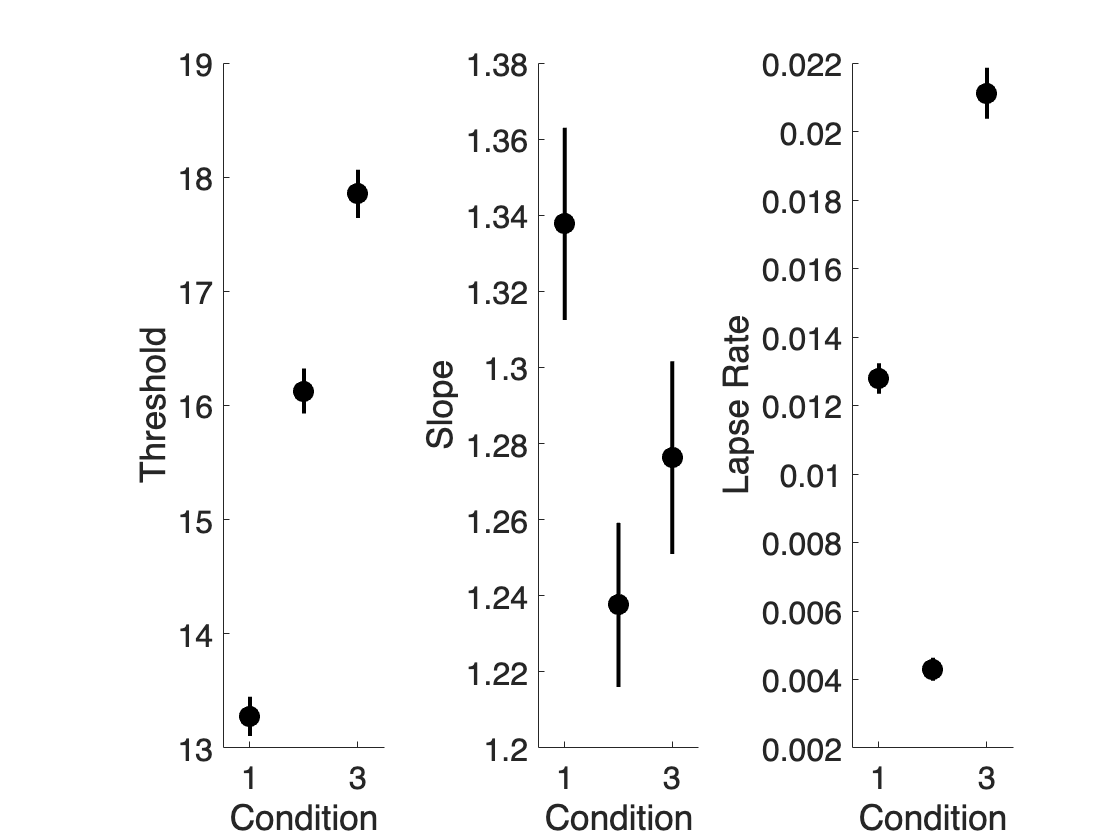

figure;
% Thresold plot
subplot(1,3,1); hold on
plot(1:3,paramsF(1:3,1),'ko','markersize',10,'markerfacecolor','k');
line([1 1],[paramsF(1,1)-SD(1,1) paramsF(1,1)+SD(1,1)],'color','k',...
    'linewidth',2);
line([2 2],[paramsF(2,1)-SD(2,1) paramsF(2,1)+SD(2,1)],'color','k',...
    'linewidth',2);
line([3 3],[paramsF(3,1)-SD(3,1) paramsF(3,1)+SD(3,1)],'color','k',...
    'linewidth',2);
xlim([.5 3.5])
set(gca, 'fontsize',16);
set(gca, 'Xtick',[1 3]);
xlabel('Condition');
ylabel('Threshold');

%Slope plot
subplot(1,3,2); hold on
plot(1:3,paramsF(1:3,2),'ko','markersize',10,'markerfacecolor','k');
line([1 1],[paramsF(1,2)-SD(1,2) paramsF(1,2)+SD(1,2)],'color','k',...
    'linewidth',2);
line([2 2],[paramsF(2,2)-SD(2,2) paramsF(2,2)+SD(2,2)],'color','k',...
    'linewidth',2);
line([3 3],[paramsF(3,2)-SD(3,2) paramsF(3,2)+SD(3,2)],'color','k',...
    'linewidth',2);
xlim([.5 3.5])
set(gca, 'fontsize',16);
set(gca, 'Xtick',[1 3]);
xlabel('Condition');
ylabel('Slope');

% Lapse rate plot
subplot(1,3,3); hold on
plot(1:3,paramsF(1:3,4),'ko','markersize',10,'markerfacecolor','k');
line([1 1],[paramsF(1,4)-SD(1,4) paramsF(1,4)+SD(1,4)],'color','k',...
    'linewidth',2);
line([2 2],[paramsF(2,4)-SD(2,4) paramsF(2,4)+SD(2,4)],'color','k',...
    'linewidth',2);
line([3 3],[paramsF(3,4)-SD(3,4) paramsF(3,4)+SD(3,4)],'color','k',...
    'linewidth',2);
xlim([.5 3.5])
set(gca, 'fontsize',16);
set(gca, 'Xtick',[1:3]);
xlabel('Condition');
ylabel('Lapse Rate');

Table to complement the figure. The textbook said that some researchers just report the table in their manuscript and let the reader judge how distinct the parameters are. 

conditionStr = ["Cone";"Rod+Cone";"Rod"];
T = table(conditionStr,paramsF(:,1),SD(:,1),paramsF(:,2),SD(:,2),paramsF(:,4),SD(:,4),VariableNames=["Condition" "Threshold" "Threshold SE" "Slope" "Slope SE" "Lapse Rate" "LapseRate SE"])

T = 3×7 table
    Condition     Threshold    Threshold SE    Slope     Slope SE    Lapse Rate    LapseRate SE
    __________    _________    ____________    ______    ________    __________    ____________

    "Cone"         13.277        0.17118       1.3377    0.025244      0.01279      0.00044469 
    "Rod+Cone"     16.127        0.19674       1.2376    0.021603    0.0042988      0.00033615 
    "Rod"          17.853        0.21091       1.2763    0.025342     0.021117      0.00074156 


## Model comparisons

"...formal procedure for determining whether differences between the PFs in different conditions are substantial enough to allow us to conclude that the parameters of the underlying true PFs are different."

The likelihood under the 2PF model will always be higher than that of the 1PF model since the 2PF model can more closely fit the nuances (or the noise) in the two conditions. The ration of the two likelihoods L_1PF/L_2PF should be between 0 and 1 where 1 means that there is no difference between the likelihoods of the 2 models. The closer to 0 that ratio is, the worse the 1PF fit is relative to the 2PF fit which means that these models are not the same. 

The p-value that comes out of all this is the number of simulations with a smaller likelihood ratio than the data divided by the number of simulations. The p-value tells you how likely it is "that an observer who acts according to the 1 PF model would produce a likelihood ratio as small or smaller than that produced by our human observer". **The p-value "is the probability of obtaining the observed data if the more restrictive model were true".** So a low p-value would say that our 3 conditions are distinct. 

It took some finagling to get the fits to match what I got before because the default settings for PAL_PFLR_ModelComparison assume that guess rates and lapse rates are fixed. So I passed some options in to change that. The paramsF0 now matches paramsF, and paramsL0 matches paramsL.

### Effect on threshold, slope, and/or lapse rate

"In the lesser model threshold parameters are constrained to be equal across conditions, as are the slope parameters. In both the fuller and lesser models, the guess rate and lapse rate parameters are fixed. As explained in the text, it is the assumptions that the lesser model makes but the fuller does not that are tested by the model comparison. Thus this model comparison tests whether the thresholds and slopes are equal in the conditions or whether differences exist."

In other words, the simulations I do below keep the threshold, slope and lapse rate for the 1PF constrained and the test tells me whether these 3 parameters are equal across the conditions or not. 

% Number of simulations to perform to determine model comparison p-values
Bmc = 10000;

% Constraints - I want the same as before
%omnibus test (2 PF vs 1 PF model, same threshold AND same slope?)
[TLR0, pTLR, paramsL0, paramsF0, TLRSim, converged] = ...
    PAL_PFLR_ModelComparison(StimLevels, NumPos, OutOfNum, paramsInit, Bmc, ...
    PF,'maxTries',maxTries,'rangeTries',rangeTries,...
    'lapseLimits',lapseLimits,'searchOptions',options,...
    'lesserLapserates','constrained','fullerLapserates','unconstrained');
% (default values indicated in curly brackets):
%       'lesserThresholds'      {'constrained'}
%       'lesserSlopes'          {'constrained'}
%       'lesserGuessrates'      {'fixed'}
%       'lesserLapserates'      {'fixed'}
%       'fullerThresholds'      {'unconstrained'}
%       'fullerSlopes'          {'unconstrained'}
%       'fullerGuessrates'      {'fixed'}
%       'fullerLapserates'      {'fixed'}

pTLR

pTLR = 0

if pTLR < 0.05
    fprintf('Result: SIGNIFICANT (p < 0.05). The curves are statistically distinct.\n');
else
    fprintf('Result: NOT SIGNIFICANT. The curves can be modeled with identical parameters.\n');
end

Result: SIGNIFICANT (p < 0.05). The curves are statistically distinct.


A figure to verify. 

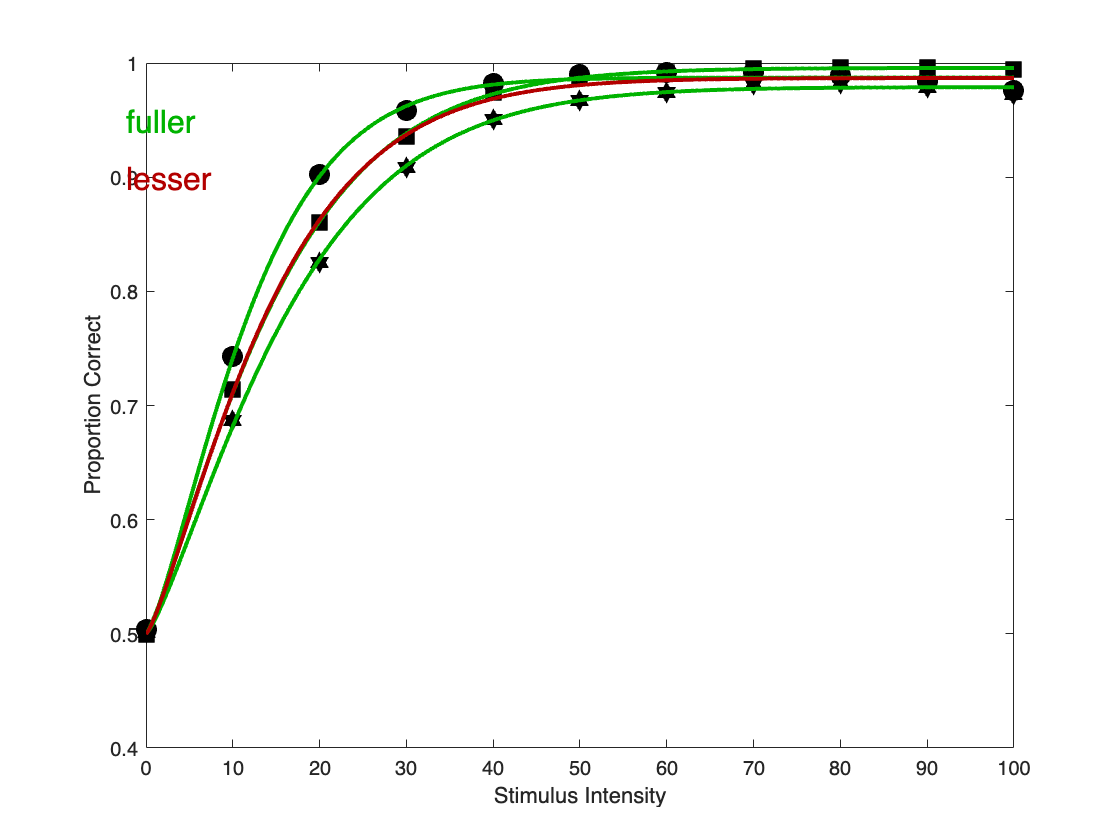

figure;
plot(StimLevels(1,:),ProportionCorrectObserved(1,:),'ko','markersize',...
    10,'markerfacecolor','k');
hold on;
plot(StimLevels(2,:),ProportionCorrectObserved(2,:),'ks','markersize',...
    10,'markerfacecolor','k');
plot(StimLevels(3,:),ProportionCorrectObserved(3,:),'kh','markersize',...
    10,'markerfacecolor','k');

ProportionCorrectModel = PF(paramsF0(1,:),StimLevelsFineGrain);
plot(StimLevelsFineGrain,ProportionCorrectModel,'-','linewidth',2,...
    'color',[0 .7 0]);
ProportionCorrectModel = PF(paramsF0(2,:),StimLevelsFineGrain);
plot(StimLevelsFineGrain,ProportionCorrectModel,'-','linewidth',2,...
    'color',[0 .7 0]);
ProportionCorrectModel = PF(paramsF0(3,:),StimLevelsFineGrain);
plot(StimLevelsFineGrain,ProportionCorrectModel,'-','linewidth',2,...
    'color',[0 .7 0]);
ProportionCorrectModel = PF(paramsL0(1,:),StimLevelsFineGrain);
plot(StimLevelsFineGrain,ProportionCorrectModel,'-','linewidth',2,...
    'color',[.7 0 0]);
xlabel('Stimulus Intensity');
ylabel('Proportion Correct');
text(-2.3,.95,'fuller','color',[0 .7 0],'FontSize',16);
text(-2.3,.9,'lesser','color',[.7 0 0],'FontSize',16);

### Calculation from Gemini

I don't quite understand how these results are identical to those above.

%% 4. Likelihood Ratio Test (LRT) Comparison
TLR1 = 2 * (LLFull - LLRestr);
NumParamsRestr = 3; % 1 Shared Threshold + 1 Shared Slope + 1 Share Lapse Rate
NumParamsFull = NumConditions*NumParamsRestr; % 2 thresholds + 2 slopes
dfree = NumParamsFull - NumParamsRestr; % Degrees of freedom (4 - 2 = 2)

% Calculate p-value using the Chi-Square Distribution
p_value = 1 - chi2cdf(TLR1, dfree);

[fprintf('--- Statistical Comparison ---\n'),fprintf('LRT Statistic (TLR): %6.2f\n', TLR1),fprintf('Degrees of Freedom: %d\n', dfree),fprintf('p-value: %e\n', p_value)];

--- Statistical Comparison ---
LRT Statistic (TLR): 1458.19
Degrees of Freedom: 6
p-value: 0.000000e+00


### Effect on threshold

From here I can do any combination of mix and match parameters to pin down an effect of just one of them or a combination of them. If pTLR is less than 0.05, "we conclude that the difference in threshold estimates between the conditions reflects a real difference in the underlying threshold parameters".

[TLR_thresh, pTLR_thresh, paramsL_thresh, paramsF_thresh, TLRSim, converged] = ...
    PAL_PFLR_ModelComparison(StimLevels, NumPos, OutOfNum, paramsInit, Bmc, ...
    PF,'maxTries',maxTries,'rangeTries',rangeTries,...
    'lapseLimits',lapseLimits,'searchOptions',options,...
    'lesserLapserates','unconstrained','fullerLapserates','unconstrained',...
    'lesserSlopes','unconstrained');
% (default values indicated in curly brackets):
%       'lesserThresholds'      {'constrained'}
%       'lesserSlopes'          {'constrained'}
%       'lesserGuessrates'      {'fixed'}
%       'lesserLapserates'      {'fixed'}
%       'fullerThresholds'      {'unconstrained'}
%       'fullerSlopes'          {'unconstrained'}
%       'fullerGuessrates'      {'fixed'}
%       'fullerLapserates'      {'fixed'}

pTLR_thresh

pTLR_thresh = 0

if pTLR_thresh < 0.05
    fprintf('Result: SIGNIFICANT (p < 0.05). The curves are statistically distinct.\n');
else
    fprintf('Result: NOT SIGNIFICANT. The curves can be modeled with identical parameters.\n');
end

Result: SIGNIFICANT (p < 0.05). The curves are statistically distinct.


### Effect on slope

If pTLR is less than 0.05, that means that the difference in slope estimates between the two conditions is real and that the two conditions genuinely have difference slopes. Note that paramsF_slope is identical to paramsF. So paramsL_slope contains the specially-constrained model. If pTLR_slope had been greater than 0.05, the model in paramsL_slope would've been the model to perform a goodness-of-fit on, according to the textbook. 

[TLR_slope, pTLR_slope, paramsL_slope, paramsF_slope, TLRSim, converged] = ...
    PAL_PFLR_ModelComparison(StimLevels, NumPos, OutOfNum, paramsInit, Bmc, ...
    PF,'maxTries',maxTries,'rangeTries',rangeTries,...
    'lapseLimits',lapseLimits,'searchOptions',options,...
    'lesserLapserates','unconstrained','fullerLapserates','unconstrained',...
    'lesserThresholds','unconstrained');

pTLR_slope

pTLR_slope = 0.0161

if pTLR_slope < 0.05
    fprintf('Result: SIGNIFICANT (p < 0.05). The curves are statistically distinct.\n');
else
    fprintf('Result: NOT SIGNIFICANT. The curves can be modeled with identical parameters.\n');
end

Result: SIGNIFICANT (p < 0.05). The curves are statistically distinct.


### Effect on lapse rate

If pTLR is less than 0.05, that means that the difference in lapse rate estimates between the two conditions is real and that the two conditions genuinely have difference lapse rates.

[TLR_LR, pTLR_LR, paramsL_LR, paramsF_LR, TLRSim, converged] = ...
    PAL_PFLR_ModelComparison(StimLevels, NumPos, OutOfNum, paramsInit, Bmc, ...
    PF,'maxTries',maxTries,'rangeTries',rangeTries,...
    'lapseLimits',lapseLimits,'searchOptions',options,...
    'lesserLapserates','constrained','fullerLapserates','unconstrained',...
    'lesserThresholds','unconstrained','lesserSlopes','unconstrained');

pTLR_LR

pTLR_LR = 0

if pTLR_LR < 0.05
    fprintf('Result: SIGNIFICANT (p < 0.05). The curves are statistically distinct.\n');
else
    fprintf('Result: NOT SIGNIFICANT. The curves can be modeled with identical parameters.\n');
end

Result: SIGNIFICANT (p < 0.05). The curves are statistically distinct.


## Goodness-of-fit

Taken together, the above tests indicate that all 3 free parameters are different between conditions. 

"A goodness-of-fit test is performed in order to test whether a particular model provides an adequate fit to some data". A high p-value here is a high goodness-of-fit.

I think I need to start out by doing the fit that I want to test. Then I'm supposed to do the Bootstrap, although I don't think that step is necessary. Anyway, I did both of those above already. I think the 2 PF model is the true model, so is that the one that I do the GOF test on?

%Goodness-of-fit
% [TLR_gof pTLR_gof TLRSim converged] =PAL_PFML_GoodnessOfFitMultiple(StimLevels, ...
%     NumPos, OutOfNum, paramsF, Bmc, PF, 'Thresholds', 'unconstrained', ...
%     'Slopes', 'unconstrained', 'GuessRates', 'fixed', 'LapseRates', 'unconstrained', ...
%     'maxTries',maxTries, 'rangeTries',rangeTries,'lapseLimits', lapseLimits, ...
%     'searchOptions', options);
[TLR_gof pTLR_gof TLRSim converged] =PAL_PFML_GoodnessOfFitMultiple(StimLevels, ...
    NumPos, OutOfNum, paramsL, Bmc, PF, 'Thresholds', 'unconstrained', ...
    'Slopes', 'unconstrained', 'GuessRates', 'fixed', 'LapseRates', 'unconstrained', ...
    'maxTries',maxTries, 'rangeTries',rangeTries,'lapseLimits', lapseLimits, ...
    'searchOptions', options);

pTLR_gof

pTLR_gof = 0

if pTLR_gof < 0.05
    fprintf('Result: (p < 0.05).\n');
else
    fprintf('Result: NOT SIGNIFICANT.\n');
end

Result: (p < 0.05).
